Francisco Moyet Vargas

Assignment 4

**Exercise 1.i**

Finding the equilibrium analitically:

syms c(t) V Q k F;
ode(t) = diff(c(t),t) == (F/V)-(Q*c/V)-(k*c^2);
F=200;V=10;Q=1;k=0.1; % to subs in symbolic function
ode(t)=subs(ode(t))

$$ode(t) = \frac{\partial }{\partial t}c\left(t\right)=-\frac{{c\left(t\right)}^{2}}{10}-\frac{c\left(t\right)}{10}+20$$

If we let c(t) = x, then we can solve for $\frac{\textrm{dc}}{\textrm{dt}}=-\frac{c^2 }{10}-\frac{c}{10}+20=-\frac{x^2 }{10}-\frac{x}{10}+20=0$:

syms g(x);
g(x) = -x^2/10-x/10+20

$$g(x) = -\frac{x^{2}}{10}-\frac{x}{10}+20$$

solve(g,x);
conc_equilib = (3*sqrt(89)/2)-0.5

conc_equilib = 13.6510

cond = c(0) == 0; % initial concentration
conc(t)=dsolve(ode(t),cond) % analytical solution

$$conc(t) = \frac{3\,\sqrt{89}\,\tanh\left(\frac{\sqrt{89}\,\left(267\,t+20\,\sqrt{89}\,\mathrm{atanh}\left(\frac{\sqrt{89}}{267}\right)\right)}{1780}\right)}{2}-\frac{1}{2}$$

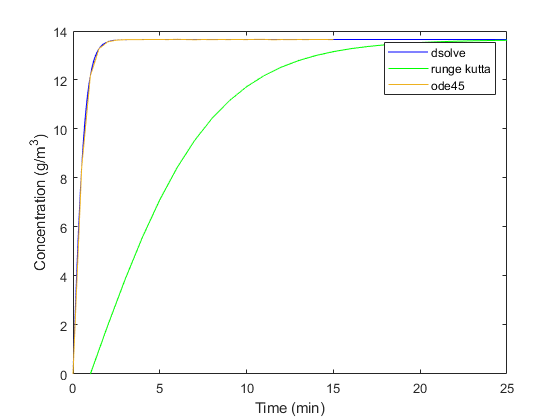

f=@func;
[a,b]=ode45(f,[0:0.5:15],0);
numerical = runge_kutta(f,[0:0.1:15],0);

fplot(conc,[0 25],'b')
xlim([0 25]);
ylim([0 14]);
hold on

plot(numerical,'g')
xlim([0 25]);
ylim([0 14]);
hold on
plot(a,b)
xlim([0 25]);
ylim([0 14]);
legend("dsolve","runge kutta","ode45");
xlabel('Time (min)');
ylabel('Concentration (g/m^3)');

The steady state concentration is $13\ldotp 6510\frac{g}{m^3 }$.  By the plot above, note that the  analytical solution grows and approach the steady state concentration more rapidly than the Runge Kutta algorithm. However, the Runge Kutta algorithm does approach the steady state later in time.

**Part (ii):**

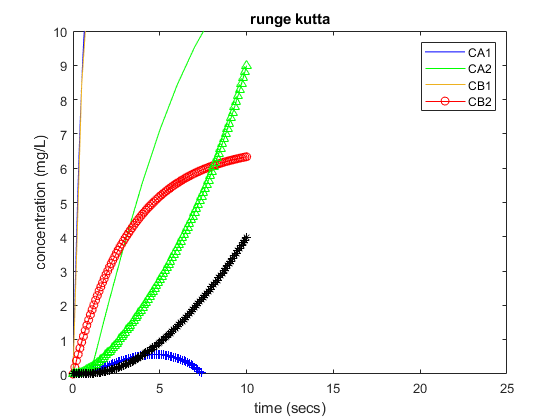

c0 = [0; 0; 0; 0]; % initial condition
t = [0:0.1:10];
[c] = runge_kutta(@chemical_reactor,t,c0);
c1=c(1,:);
c2=c(2,:);
c3=c(3,:);
c4=c(4,:);
figure(1)
plot(t,c1,'-ro',t,c2,'-b+',t,c3,'-g^',t,c4,'-k*');
legend('CA1','CA2','CB1','CB2');
xlabel('time (secs)');
ylabel('concentration (mg/L)');
title('runge kutta')
hold off;
ylim([0,10])
% ode 45:
figure(2)
ode45(@chemical_reactor,[0 10],c0)

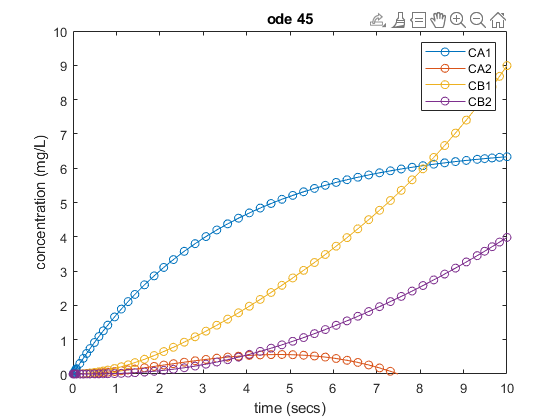

legend('CA1','CA2','CB1','CB2');
title('ode 45')
xlabel('time (secs)');
ylabel('concentration (mg/L)');
ylim([0,10])

function [dcdt] = chemical_reactor(t,c)
dcdt = zeros(4,1); % 4 equations
dcdt(1)=(1/5)*(10-c(1))-0.1*c(1);
dcdt(2)=-(1/5)*c(3)+0.1*c(1);
dcdt(3)=(1/5)*(c(1)-c(2))-0.1*c(2);
dcdt(4)=(1/5)*(c(3)-c(4))+0.1*c(2);
 
end
function [y] = runge_kutta(df,x,y0)
m = length(y0);
n = length(x);
% y is a matrix of size 'mxn'
y=zeros(m,n);
y(:,1)=y0;
for i=1:n-1
    h = x(i+1)-x(i);
    xi=x(i);
    yi=y(:,i);
    k1 = feval(df,xi,yi);
    k2 = feval(df,xi+0.5*h,yi+0.5*k1*h);
    k3 = feval(df,xi+0.5*h,yi+0.5*k2*h);
    k4 = feval(df,xi+h,yi+k3*h);
    y(:,i+1) = y(:,i) + h*(k1+2*k2+2*k3+k4)/6;
end
end


function [dcdt] = func(t,c)
V=10;F=200;Q=1;k=0.1;
dcdt=zeros(1,1);
dcdt(1) = (F/V)-(Q*c./V)-k.*c.^2;
end

function [dxdt] = odefunc(t,c)
dxdt = zeros(4,1); % 4 equations

dxdt(1)=(1/5)*(10-c(1))-0.1*c(1);
dxdt(2)=-(1/5)*c(3)+0.1*c(1);
dxdt(3)=(1/5)*(c(1)-c(2))-0.1*c(2);
dxdt(4)=(1/5)*(c(3)-c(4))+0.1*c(2);

end